clear;
data = readtable('result\data3.csv')

data = 24×19 table
    year    people_gdp      income         GDP         SO2      Lib        Stu        people_num    Urban     people_incom      Carbon       Big     Medium      Small        industry       energy        Var17         Var18         Var19  
    ____    __________    __________    __________    ______    ____    __________    __________    ______    ____________    __________    _____    ______    __________    __________    __________    __________    __________    _________

    2000       7942            99066    1.0028e+05    3760.6    2675     9.498e+05    1.2674e+05    0.3622       3721.3       3.3465e+06    21724    13741     1.4116e+05    1.0301e+09     4.233e+07    {'93.02%'}    {'6.98%' }    {'0.00%'}
    2001       8717       1.0928e+05    1.1086e+05    3637.7    2696    1.0363e+06    1.2763e+05    0.3766       4070.4       3.5291e+06    22987    14398     1.4827e+05    1.0714e+09    4.1152e+07    {'91.24%'}    {'8.76%' }    {'0.00%'}
    2002       9506     

people_num = vertcat(data{1:21,8});
urbanization = vertcat(data{1:21,9});
people_gdp = vertcat(data{:,2});
GDP = vertcat(data{:,4});
Income = vertcat(data{1:21,10});
Libary = vertcat(data{1:21,6});
industry_energy = vertcat(data{1:21,15});
others_energy = vertcat(data{1:21,16});
num_big = vertcat(data{1:21,12});
num_medium = vertcat(data{1:21,13});
num_small = vertcat(data{1:21,14});
SO2 = vertcat(data{1:21,5});
Student = vertcat(data{1:21,7});
carbon = vertcat(data{1:21,11});

% 人口数据拟合 R = 0.997
X = (2000:2020)'

X =         2000
        2001
        2002
        2003
        2004
        2005
        2006
        2007
        2008
        2009


Y = people_num

函数或变量 'people_num' 无法识别。


mdl = fitlm(X, Y);
param = (vertcat(mdl.Coefficients{:,1}))'
disp(mdl);
a = anova(mdl,'summary')
pf = vertcat(a{2,4:5})'
pfs = [pf;mdl.Rsquared.Ordinary;mdl.Rsquared.Adjusted;];
cla;
plot(mdl);

% 工业排放与工厂数量、人均GDP拟合 R = 0.99
X = [num_big, num_medium, num_small, GDP(1:21), SO2]

X = 1.0e+06 *

    0.0217    0.0137    0.1412    0.1003    0.0038
    0.0230    0.0144    0.1483    0.1109    0.0036
    0.0233    0.0146    0.1582    0.1217    0.0036
    0.0236    0.0216    0.1726    0.1374    0.0041
    0.0277    0.0256    0.2488    0.1618    0.0045
    0.0298    0.0273    0.2421    0.1873    0.0051
    0.0329    0.0302    0.2690    0.2194    0.0052
    0.0365    0.0336    0.3003    0.2701    0.0049
    0.0404    0.0372    0.3857    0.3192    0.0046
    0.0413    0.0380    0.3931    0.3485    0.0044


Y = industry_energy

Y = 1.0e+09 *

    1.0301
    1.0714
    1.1360
    1.3117
    1.5251
    1.8791
    1.8495
    2.0053
    2.0930
    2.4357



mdl = fitlm(X, Y);
param = [param, (vertcat(mdl.Coefficients{:,1}))']

param = 1.0e+07 *

   -0.1372    0.0001    5.2883   -0.0005    0.0018    0.0001    0.0002    0.0125


disp(mdl);

线性回归模型:
    y ~ 1 + x1 + x2 + x3 + x4 + x5

估计系数:
                    Estimate         SE         tStat        pValue  
                   __________    __________    ________    __________

    (Intercept)    5.2883e+07    2.2813e+08     0.23181       0.81982
    x1                -4670.3         12351    -0.37813       0.71063
    x2                  18490         15312      1.2075       0.24592
    x3                 1083.4        550.97      1.9664      0.068044
    x4                 2221.5           327      6.7936    6.0582e-06
    x5             1.2525e+05         50055      2.5022      0.024399


观测值数目: 21，误差自由度: 15
均方根误差: 9.11e+07
R 方: 0.99，调整 R 方 0.986
F 统计量(常量模型): 285，p 值 = 2.57e-14


a = anova(mdl,'summary');
pf = vertcat(a{2,4:5})'

pf =   285.4979
    0.0000


pf2 = [pf;mdl.Rsquared.Ordinary;mdl.Rsquared.Adjusted;];
pfs = [pfs,pf2]

pfs = 1.0e+03 *

    7.4275    0.2855
    0.0000    0.0000
    0.0010    0.0010
    0.0010    0.0010


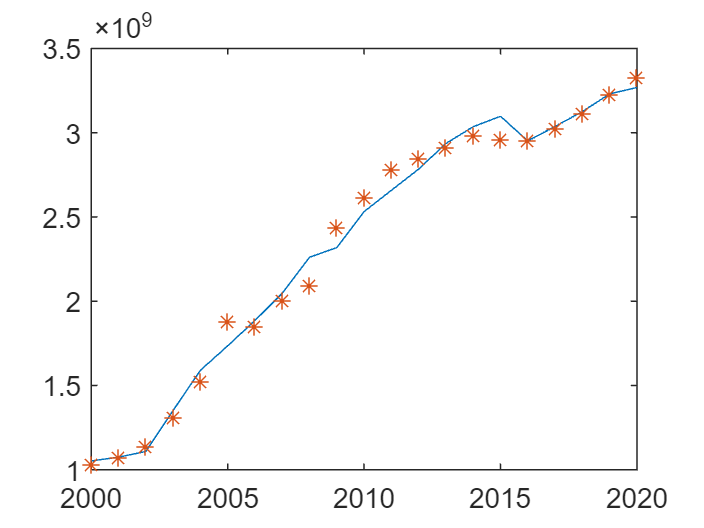

y_pre = predict(mdl,X);
plot(2000:2020,y_pre,'-',2000:2020,Y,'*');

% 碳排放与能源消耗拟合 R = 0.994
X = [industry_energy+others_energy]

X = 1.0e+09 *

    1.0725
    1.1125
    1.1793
    1.3612
    1.5820
    1.9477
    1.9128
    2.0676
    2.1532
    2.5055


Y = carbon

Y = 1.0e+07 *

    0.3347
    0.3529
    0.3796
    0.4424
    0.5113
    0.5825
    0.6437
    0.6993
    0.7200
    0.7719



mdl = fitlm(X, Y);
param = [param, (vertcat(mdl.Coefficients{:,1}))']

param = 1.0e+07 *

   -0.1372    0.0001    5.2883   -0.0005    0.0018    0.0001    0.0002    0.0125   -0.0090    0.0000


disp(mdl);

线性回归模型:
    y ~ 1 + x1

估计系数:
                   Estimate         SE         tStat        pValue  
                   _________    __________    ________    __________

    (Intercept)       -90188    1.4684e+05    -0.61419       0.54637
    x1             0.0032772    5.8094e-05      56.412    1.2754e-22


观测值数目: 21，误差自由度: 19
均方根误差: 2.05e+05
R 方: 0.994，调整 R 方 0.994
F 统计量(常量模型): 3.18e+03，p 值 = 1.28e-22


a = anova(mdl,'summary');
pf = vertcat(a{2,4:5})'

pf = 1.0e+03 *

    3.1823
    0.0000


pf2 = [pf;mdl.Rsquared.Ordinary;mdl.Rsquared.Adjusted;];
pfs = [pfs,pf2]

pfs = 1.0e+03 *

    7.4275    0.2855    3.1823
    0.0000    0.0000    0.0000
    0.0010    0.0010    0.0010
    0.0010    0.0010    0.0010


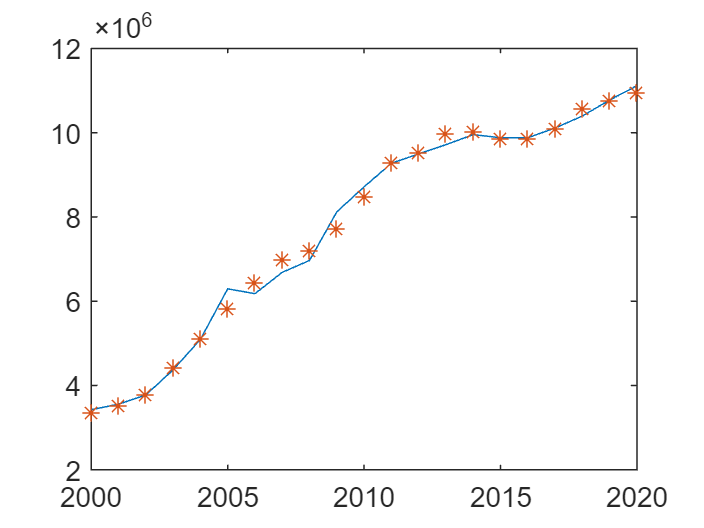

y_pre = predict(mdl,X);
plot(2000:2020,y_pre,'-',2000:2020,Y,'*');

% 城镇化与GDP、本专科毕业生拟合 R = 0.996
X = [GDP(1:21),Student]

X = 1.0e+06 *

    0.1003    0.9498
    0.1109    1.0363
    0.1217    1.3373
    0.1374    1.8775
    0.1618    2.3912
    0.1873    3.0680
    0.2194    3.7747
    0.2701    4.4779
    0.3192    5.1195
    0.3485    5.3110


Y = urbanization

Y =     0.3622
    0.3766
    0.3909
    0.4053
    0.4176
    0.4299
    0.4434
    0.4589
    0.4699
    0.4834



mdl = fitlm(X, Y);
param = [param, (vertcat(mdl.Coefficients{:,1}))']

param = 1.0e+07 *

   -0.1372    0.0001    5.2883   -0.0005    0.0018    0.0001    0.0002    0.0125   -0.0090    0.0000    0.0000    0.0000    0.0000


disp(mdl);

线性回归模型:
    y ~ 1 + x1 + x2

估计系数:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)       0.34525     0.0034982    98.694    4.5882e-26
    x1             1.7199e-07    1.1533e-08    14.913    1.4214e-11
    x2             1.5204e-08    1.5073e-09    10.087    7.8182e-09


观测值数目: 21，误差自由度: 18
均方根误差: 0.006
R 方: 0.996，调整 R 方 0.995
F 统计量(常量模型): 2.1e+03，p 值 = 4.75e-22


a = anova(mdl,'summary');
pf = vertcat(a{2,4:5})'

pf = 1.0e+03 *

    2.0971
    0.0000


pf2 = [pf;mdl.Rsquared.Ordinary;mdl.Rsquared.Adjusted;];
pfs = [pfs,pf2]

pfs = 1.0e+03 *

    7.4275    0.2855    3.1823    2.0971
    0.0000    0.0000    0.0000    0.0000
    0.0010    0.0010    0.0010    0.0010
    0.0010    0.0010    0.0010    0.0010


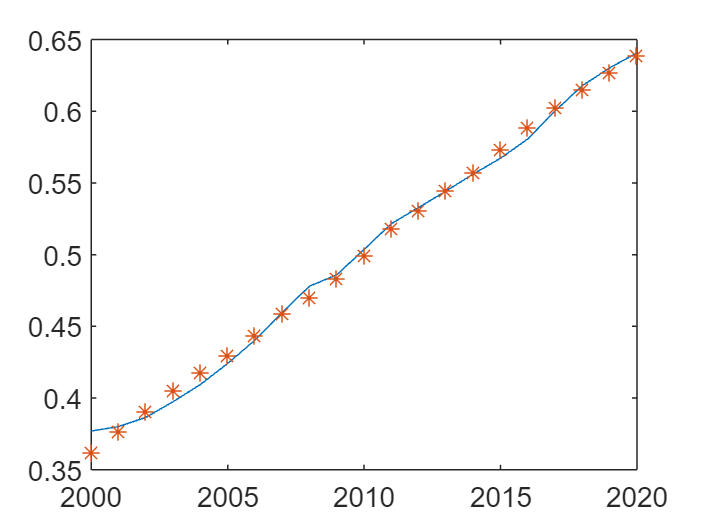

cla;
y_pre = predict(mdl,X);
plot(2000:2020,y_pre,'-',2000:2020,Y,'*');

% 人均GDP 与 城镇化、图书馆、工厂数量拟合 R = 0.997
X = [urbanization, Libary, Student]

X = 1.0e+06 *

    0.0000    0.0027    0.9498
    0.0000    0.0027    1.0363
    0.0000    0.0027    1.3373
    0.0000    0.0027    1.8775
    0.0000    0.0027    2.3912
    0.0000    0.0028    3.0680
    0.0000    0.0028    3.7747
    0.0000    0.0028    4.4779
    0.0000    0.0028    5.1195
    0.0000    0.0029    5.3110


Y = people_gdp(1:21)

Y =         7942
        8717
        9506
       10666
       12487
       14368
       16738
       20494
       24100
       26180



mdl = fitlm(X, Y);
param = [param, (vertcat(mdl.Coefficients{:,1}))']

param = 1.0e+07 *

   -0.1372    0.0001    5.2883   -0.0005    0.0018    0.0001    0.0002    0.0125   -0.0090    0.0000    0.0000    0.0000    0.0000   -0.0136    0.0343    0.0000   -0.0000


disp(mdl);

线性回归模型:
    y ~ 1 + x1 + x2 + x3

估计系数:
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)    -1.3613e+05         23384    -5.8213    2.0435e-05
    x1              3.4267e+05         43280     7.9175    4.2017e-07
    x2                  6.8557        13.115    0.52274        0.6079
    x3              -0.0043441    0.00095441    -4.5516    0.00028276


观测值数目: 21，误差自由度: 17
均方根误差: 2.33e+03
R 方: 0.99，调整 R 方 0.988
F 统计量(常量模型): 563，p 值 = 3.3e-17


a = anova(mdl,'summary');
pf = vertcat(a{2,4:5})'

pf =   563.2757
    0.0000


pf2 = [pf;mdl.Rsquared.Ordinary;mdl.Rsquared.Adjusted;];
pfs = [pfs,pf2]

pfs = 1.0e+03 *

    7.4275    0.2855    3.1823    2.0971    0.5633
    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0010    0.0010    0.0010    0.0010    0.0010
    0.0010    0.0010    0.0010    0.0010    0.0010


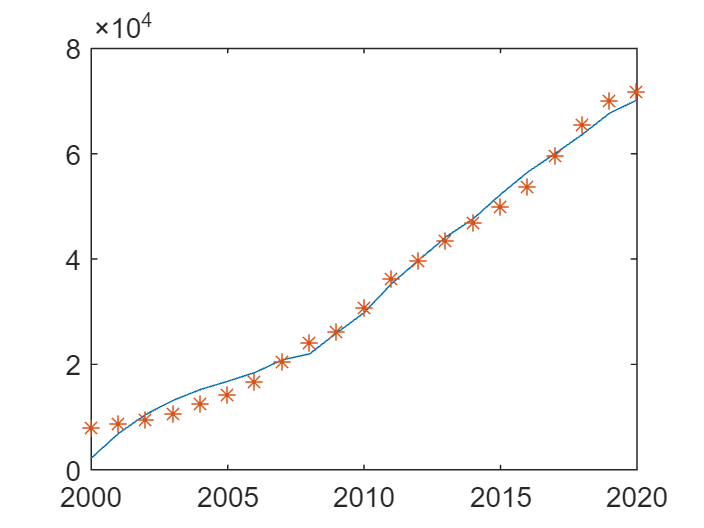

cla;
y_pre = predict(mdl,X);
plot(2000:2020,y_pre,'-',2000:2020,Y,'*');

% GDP 与 人均GDP、人口数量 拟合  R = 1
X = people_num.* people_gdp(1:21)

X = 1.0e+10 *

    0.1007
    0.1113
    0.1221
    0.1378
    0.1623
    0.1879
    0.2200
    0.2708
    0.3201
    0.3494


Y = GDP(1:21)

Y = 1.0e+06 *

    0.1003
    0.1109
    0.1217
    0.1374
    0.1618
    0.1873
    0.2194
    0.2701
    0.3192
    0.3485



mdl = fitlm(X, Y);
param = [param, (vertcat(mdl.Coefficients{:,1}))']

param = 1.0e+07 *

   -0.1372    0.0001    5.2883   -0.0005    0.0018    0.0001    0.0002    0.0125   -0.0090    0.0000    0.0000    0.0000    0.0000   -0.0136    0.0343    0.0000   -0.0000   -0.0000    0.0000


disp(mdl);

线性回归模型:
    y ~ 1 + x1

估计系数:
                    Estimate         SE         tStat      pValue  
                   __________    __________    _______    _________

    (Intercept)       -349.56        196.13    -1.7823     0.090691
    x1             9.9826e-05    3.5187e-08     2837.1    6.317e-55


观测值数目: 21，误差自由度: 19
均方根误差: 484
R 方: 1，调整 R 方 1
F 统计量(常量模型): 8.05e+06，p 值 = 6.32e-55


a = anova(mdl,'summary');
pf = vertcat(a{2,4:5})'

pf = 1.0e+06 *

    8.0489
    0.0000


pf2 = [pf;mdl.Rsquared.Ordinary;mdl.Rsquared.Adjusted;];
pfs = [pfs,pf2]

pfs = 1.0e+06 *

    0.0074    0.0003    0.0032    0.0021    0.0006    8.0489
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


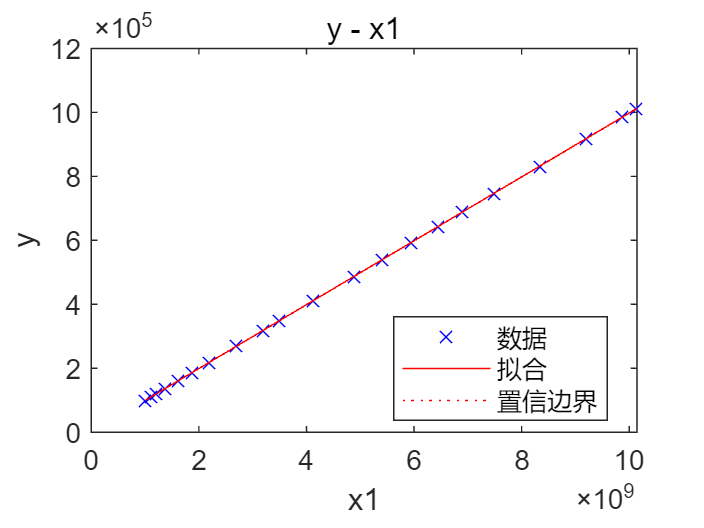

cla;
plot(mdl);

% 图书馆 与 GDP、学生拟合  R = 0.957
X = [GDP(1:21),Student]

X = 1.0e+06 *

    0.1003    0.9498
    0.1109    1.0363
    0.1217    1.3373
    0.1374    1.8775
    0.1618    2.3912
    0.1873    3.0680
    0.2194    3.7747
    0.2701    4.4779
    0.3192    5.1195
    0.3485    5.3110


Y = Libary

Y =         2675
        2696
        2697
        2709
        2720
        2762
        2778
        2799
        2820
        2850



mdl = fitlm(X, Y);
param = [param, (vertcat(mdl.Coefficients{:,1}))']

param = 1.0e+07 *

   -0.1372    0.0001    5.2883   -0.0005    0.0018    0.0001    0.0002    0.0125   -0.0090    0.0000    0.0000    0.0000    0.0000   -0.0136    0.0343    0.0000   -0.0000   -0.0000    0.0000    0.0003    0.0000    0.0000


disp(mdl);

线性回归模型:
    y ~ 1 + x1 + x2

估计系数:
                    Estimate         SE        tStat       pValue  
                   __________    __________    ______    __________

    (Intercept)        2600.6        25.667    101.32    2.8625e-26
    x1              0.0004683    8.4621e-05    5.5341    2.9666e-05
    x2             2.3579e-05     1.106e-05     2.132      0.047037


观测值数目: 21，误差自由度: 18
均方根误差: 44
R 方: 0.957，调整 R 方 0.952
F 统计量(常量模型): 198，p 值 = 5.45e-13


a = anova(mdl,'summary');
pf = vertcat(a{2,4:5})'

pf =   198.4200
    0.0000


pf2 = [pf;mdl.Rsquared.Ordinary;mdl.Rsquared.Adjusted;];
pfs = [pfs,pf2]

pfs = 1.0e+06 *

    0.0074    0.0003    0.0032    0.0021    0.0006    8.0489    0.0002
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


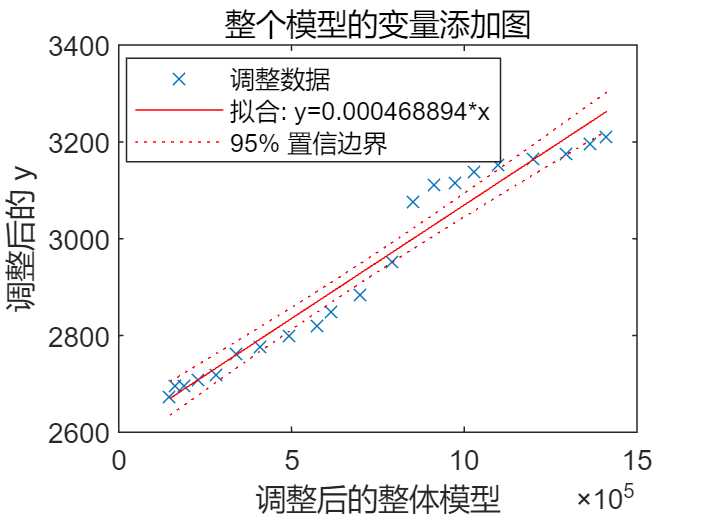

cla;
plot(mdl);

% 其他能量消耗
X = [people_num,GDP(1:21),urbanization]

X = 1.0e+06 *

    0.1267    0.1003    0.0000
    0.1276    0.1109    0.0000
    0.1285    0.1217    0.0000
    0.1292    0.1374    0.0000
    0.1300    0.1618    0.0000
    0.1308    0.1873    0.0000
    0.1314    0.2194    0.0000
    0.1321    0.2701    0.0000
    0.1328    0.3192    0.0000
    0.1335    0.3485    0.0000


Y = others_energy

Y =     42330000
    41152000
    43311800
    49546000
    56973500
    68600000
    63307100
    62284000
    60131300
    69780000



mdl = fitlm(X, Y);
param = [param, (vertcat(mdl.Coefficients{:,1}))']

param = 1.0e+08 *

   -0.0137    0.0000    0.5288   -0.0000    0.0002    0.0000    0.0000    0.0013   -0.0009    0.0000    0.0000    0.0000    0.0000   -0.0014    0.0034    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.5396   -0.0000   -0.0000    3.6593


disp(mdl);

线性回归模型:
    y ~ 1 + x1 + x2 + x3

估计系数:
                    Estimate          SE          tStat       pValue 
                   ___________    __________    _________    ________

    (Intercept)    -5.3963e+07    4.6029e+08     -0.11724     0.90805
    x1                 -273.92          4346    -0.063026     0.95048
    x2                 -48.214        16.429      -2.9347    0.009255
    x3              3.6593e+08    2.5899e+08        1.413     0.17572


观测值数目: 21，误差自由度: 17
均方根误差: 3.53e+06
R 方: 0.961，调整 R 方 0.954
F 统计量(常量模型): 141，p 值 = 3.38e-12


a = anova(mdl,'summary');
pf = vertcat(a{2,4:5})'

pf =   140.5687
    0.0000


pf2 = [pf;mdl.Rsquared.Ordinary;mdl.Rsquared.Adjusted;];
pfs = [pfs,pf2]

pfs = 1.0e+06 *

    0.0074    0.0003    0.0032    0.0021    0.0006    8.0489    0.0002    0.0001
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


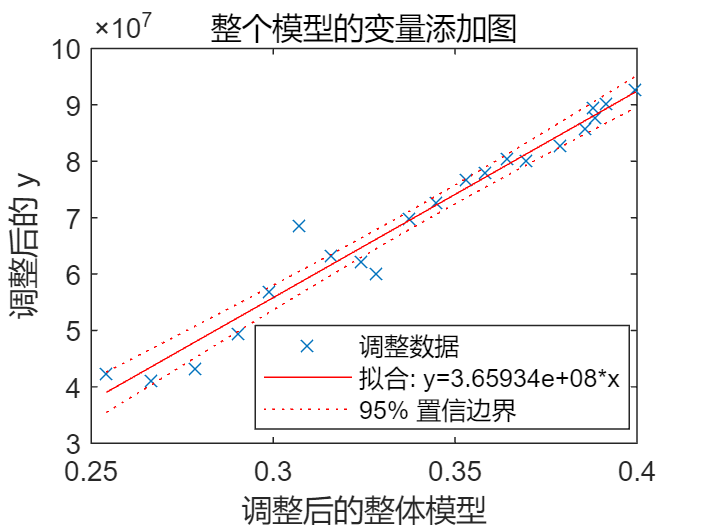

cla;
plot(mdl);

% 工厂
x = 2000:2020

x =         2000        2001        2002        2003        2004        2005        2006        2007        2008        2009        2010        2011        2012        2013        2014        2015        2016        2017        2018        2019        2020


Y1 = num_big';
Y2 = num_medium';
Y3 = num_small';

p1 = fitlm(x, Y1);
p2 = fitlm(x, Y2);
p3 = fitlm(x, Y3);

param = [param, (vertcat(p1.Coefficients{:,1}))']

param = 1.0e+08 *

   -0.0137    0.0000    0.5288   -0.0000    0.0002    0.0000    0.0000    0.0013   -0.0009    0.0000    0.0000    0.0000    0.0000   -0.0014    0.0034    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.5396   -0.0000   -0.0000    3.6593   -0.0415    0.0000


param = [param, (vertcat(p2.Coefficients{:,1}))']

param = 1.0e+08 *

   -0.0137    0.0000    0.5288   -0.0000    0.0002    0.0000    0.0000    0.0013   -0.0009    0.0000    0.0000    0.0000    0.0000   -0.0014    0.0034    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.5396   -0.0000   -0.0000    3.6593   -0.0415    0.0000   -0.0365    0.0000


param = [param, (vertcat(p3.Coefficients{:,1}))']

param = 1.0e+08 *

   -0.0137    0.0000    0.5288   -0.0000    0.0002    0.0000    0.0000    0.0013   -0.0009    0.0000    0.0000    0.0000    0.0000   -0.0014    0.0034    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.5396   -0.0000   -0.0000    3.6593   -0.0415    0.0000   -0.0365    0.0000   -0.1720    0.0001


% 学生 
X = [people_num,GDP(1:21)]

X = 1.0e+06 *

    0.1267    0.1003
    0.1276    0.1109
    0.1285    0.1217
    0.1292    0.1374
    0.1300    0.1618
    0.1308    0.1873
    0.1314    0.2194
    0.1321    0.2701
    0.1328    0.3192
    0.1335    0.3485


Y = Student

Y =       949800
     1036300
     1337300
     1877492
     2391152
     3067956
     3774708
     4477907
     5119498
     5311023



mdl = fitlm(X, Y);
param = [param, (vertcat(mdl.Coefficients{:,1}))']

param = 1.0e+08 *

   -0.0137    0.0000    0.5288   -0.0000    0.0002    0.0000    0.0000    0.0013   -0.0009    0.0000    0.0000    0.0000    0.0000   -0.0014    0.0034    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.5396   -0.0000   -0.0000    3.6593   -0.0415    0.0000   -0.0365    0.0000   -0.1720    0.0001   -1.1121    0.0000   -0.0000


disp(mdl);

线性回归模型:
    y ~ 1 + x1 + x2

估计系数:
                    Estimate          SE         tStat       pValue  
                   ___________    __________    _______    __________

    (Intercept)    -1.1121e+08    1.5027e+07    -7.4003    7.2994e-07
    x1                  885.86        117.93     7.5119    5.9358e-07
    x2                 -6.1092        1.7877    -3.4173     0.0030714


观测值数目: 21，误差自由度: 18
均方根误差: 4.62e+05
R 方: 0.965，调整 R 方 0.961
F 统计量(常量模型): 250，p 值 = 7.37e-14


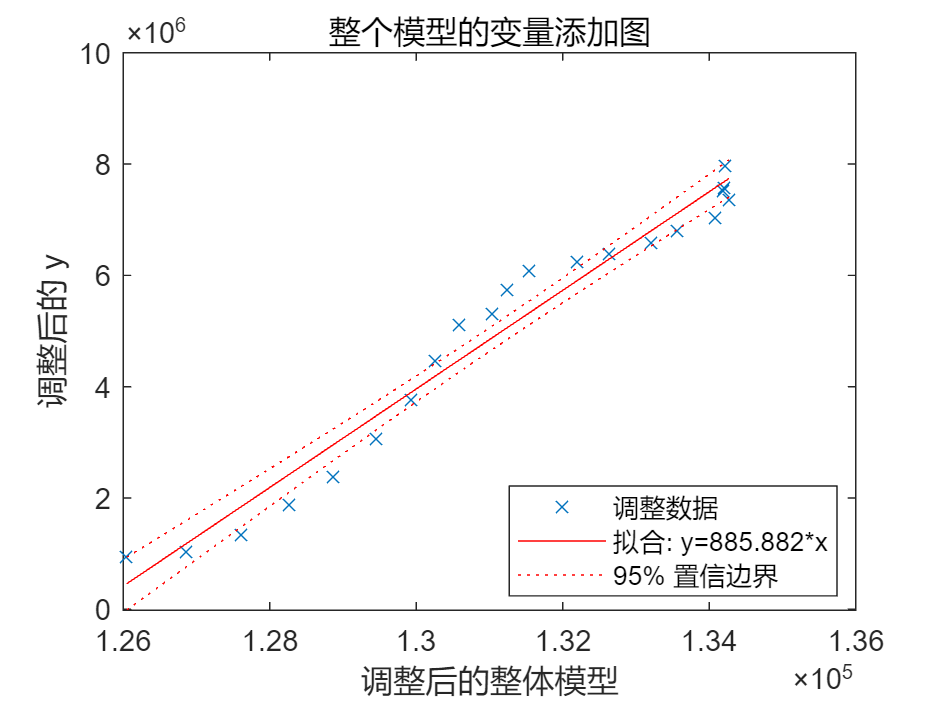

cla;
plot(mdl);

% SO2
X = (2000:2020)'

X =         2000
        2001
        2002
        2003
        2004
        2005
        2006
        2007
        2008
        2009


Y = SO2

Y = 1.0e+03 *

    3.7606
    3.6377
    3.6186
    4.1255
    4.5101
    5.0989
    5.1755
    4.9362
    4.6426
    4.4288



mdl = fitlm(X, Y);
param = [param, (vertcat(mdl.Coefficients{:,1}))']

param = 1.0e+08 *

   -0.0137    0.0000    0.5288   -0.0000    0.0002    0.0000    0.0000    0.0013   -0.0009    0.0000    0.0000    0.0000    0.0000   -0.0014    0.0034    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.5396   -0.0000   -0.0000    3.6593   -0.0415    0.0000   -0.0365    0.0000   -0.1720    0.0001   -1.1121    0.0000   -0.0000    0.0034   -0.0000


disp(mdl);

线性回归模型:
    y ~ 1 + x1

估计系数:
                    Estimate      SE       tStat       pValue  
                   __________    _____    _______    __________

    (Intercept)    3.3957e+05    77406     4.3869      0.000317
    x1                -167.18    38.51    -4.3413    0.00035171


观测值数目: 21，误差自由度: 19
均方根误差: 1.07e+03
R 方: 0.498，调整 R 方 0.472
F 统计量(常量模型): 18.8，p 值 = 0.000352


cla;
plot(mdl);

% 煤炭


writematrix(pfs, 'result\1.csv');